# MATLAB Tutorial

In this tutorial, we will explore some of the basic commands in MATLAB and how you interact with it.

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

addpath ../data   % this line provides access to datasets used in this document

## Preface

While this document is meant to help you start using MATLAB, many of the principles are common or similar to other programming languages.  If you haven't programmed before it isn't as hard as it may seem at first, though there is a fairly steep learning curve because you may need to know a lot at once.  But do not be discouraged if you produce lots of errors when you first start coding, though I won't deny it can be frustrating at times.  Every error is an opportunity to learn why something didn't work.  Purposefully break lines to see what types of errors you get.  It is highly unlikely that you will break MATLAB so don't be afraid to try things.

As you learn to write code, test it often (possibly even one line at a time) so that you can spot your errors early and correct them.  Keep in mind that an error on a given line may occur because of something you did or setup incorrectly on an earlier line.

My last bit of advice is that a program will do exactly what you tell it to do, not what you want it to do.  But that means you need to know the answer, or at least a vague idea of what it should be, before you start.  A program is also linear, performing each line of code before advancing to the next.

## 1. Starting MATLAB

To start MATLAB, locate the program on the start menu (on Windows) or in the applications Launchpad (on Mac) and click to start.  MATLAB will take a few moments to load.  Once MATLAB loads, you will see a number of panels within the main window probably in the default configuration shown below.

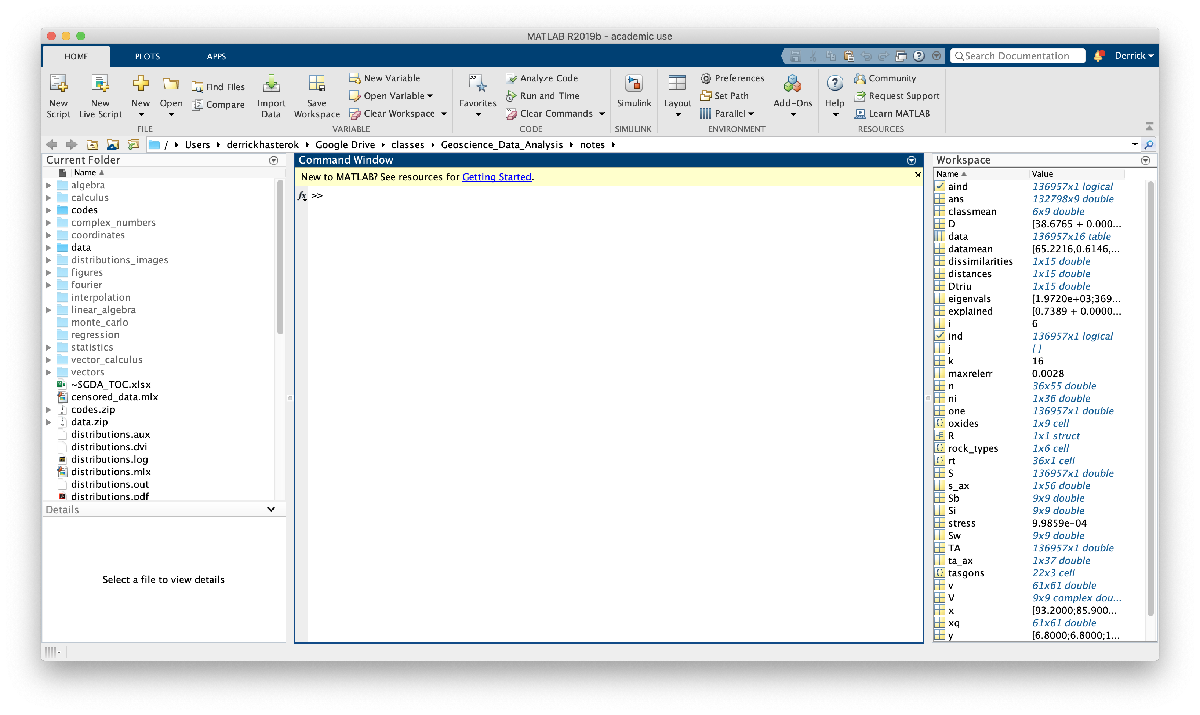

Because I have been doing some work in mine there are few differences in the initial look, but we'll get to those.  At the top just below the toolbars is the location bar.  The path that is listed is the current working directory.  MATLAB will use it as the default location to save files while you work.  You can change directories here using the icons to the left of the path.  I am currently not in the default directory.

There are four panels below the location bar.  The main panel in the center is called the Command Window, which is where you will type commands and perhaps run scripts.  MATLAB will print results of requested operations here for you to view.  The panel on the top left of the Command Window is the listing of the Current Folder.  Files with a *.m extension are either MATLAB script files or functions, files with a *.mat extension are saved variables/data, and files with a *.mlx extension are live scripts like the one used to create this document.  The small panel just below the Current Directory is the Details panel, which will display information about a current file if possible.  For functions stored in *.m file selected in the Current Directoy the Details panel will give the help text, which provides information about running the function.  The panel to the right of the Command Window is the Workspace, which shows all variables currently stored by MATLAB that are accessible to you.  Yours will probably be blank when MATLAB first opens.  You can see mine is filled with a number of variables as I have been running some codes.  The Workspace has two columns the right is the variable name.  You can print out the contents of the variable simply by typing it in the Command Window.  The left column contains either the value(s) stored in the variable, or indicates the size (number of rows x number of columns) and the variable type (e.g. double, char, cell, logical, table, etc.).

If you double click on one of the variables, MATLAB will open the Variables panel that can be used to investigate the contents.  This can be particularly useful for viewing arrays (vectors/matrices) whos values are not listed by default in the Workspace.  The other panel that will open if you open a file to edit will be the Editor, which is where you can create scripts, functions and live scripts, or occasionally open a data file.

Any of the panels can be undocked, placing it in a separate window by clicking on the small triangle in the upper right corner of the panel and selecting the Undock option.  It can be redocked by moving the window back over the main window.  You can also close any panels you do not want to use by selecting layout at from the toolbar at the top.

I'm old school and don't use most of these panels.  I undock my Editor and place it on a second screen or scale it to fit half of my screen horizontally, allowing my Command workspace to fill the other half.  I can access all of the same information by using commands in the Command Window.  I can view the contents of the current folder by typing 

 or 

 in the Command Window.  To get help on how to use a function, in the Command Window, type 

where *function_name* is the name of the file containing the function.  Help will work for any native MATLAB function as well.  To see what variables are currently stored in memory, type 

 in the Command Window.  To view the information stored in any variable, simply typing its name in the Command Window.  Sometimes I will use whos in a code I am running to track down bugs, errors, in the code.

Once you start running processes in MATLAB, you may find that you will want to organize your functions or data into folders.  You can still access the data/functions by explicitly using the path in commands you type, or you can use '*addpath*' so that MATLAB will automatically search them for the appropriate file when requested.  For example, if I want to access functions in the directory called codes stored in the current working directory, I will type

in the Command Window.

It is possible to have multiple *.m functions that have the same name on the same machine.  They may be stored in different places, but both accessible to MATLAB.  However, MATLAB has a preference.  If the code you run doesn't give what you expect and you suspect it is because it is using the wrong version, you can check using

and the path to the version that is used will be printed in the Command Window.

## 2. Errors and Warnings

You will make mistakes when you write code (I do all the time and I have been writing code since I was 16).  It is not the end of the world, you are unlikely to have broken anything.  There are four types of errors:

- error - An error flag is thrown by the code, which results in a warning being printed in the command line along with the line on which the error occurs.  The code will then stop running at this point and you will have to fix it.  You can click on the line and it will take you to the location where the error occurs so that you can find it and fix it.

- warning - A warning flag is thrown when the code thinks it found a problem that may impact the results that you produce.  A warning will not stop code from running.  Many times the warnings can be ignored.  For example you will see lots of warnings listed in this live script, but none of them produce unexpected or unintended results.

- silent error - A silent error will not result in an error or a warning.  It is the type of error that causes an incorrect result but is not outside the bounds of what the function can do.  These errors can be difficult to track down, but could be created with an incorrect equation, incorrect index into a matrix, or passing the wrong variable to a function.

- catastrophic error - It is possible to create an error so catastrophic that it MATLAB crashes.  When this happens it is almost always when you use up too much memory or accidently overwrite some operating memory that interferes with MATLAB's ability to function.  The latter is known as a segmentation fault and maybe proceeded by MATLAB spewing a bunch of red text in the command window (hex code locations for the memory error).  MATLAB may still be usable at this point, though sometimes it will result in nonsense and you will need to restart MATLAB.  It is generally hard to do this since MATLAB watches for these types of issues and dynamically creates more memory for variables or will generally causes an error when it cannot.  But there are some exceptions, often ones that MATLAB forgot to fix and may fix in a future update.  Regardless, if it happens, don't panic, just restart MATLAB and display the progress of your code by printing out variables occasionally and watch the output until the code dies.  Then try and fix the code at the point that it stopped functioning as you expected.

## 3. Basic operations

### 3.1 Commands

A few things to note before we start using MATLAB.  Any line of code that is preceded by % is a comment and will be ignored by MATLAB.

Lines of code that end with a semicolon (;) will not print the results of the operation.  If a line lacks the semicolon, it will print the results of an operation.  In general you will not want to print most lines, especially when they represent very large arrays or tables.  Printing results also slows down the code.

% result below will print (this line is ignored)
a = 5

a = 5

% result below will not (this line is ignored too)
b = 10;

To store a variable, decide a name.  A variable name can be composed of letters, numbers and _.  The name cannot contain spaces and must start with character.  MATLAB is case sensitive.  The name of variables that will be used multiple times and in several places in the code should be simple, memorable, and generally convey some idea of what it represents or stores.  We are no longer constrained to 8 characters for variable names so no need to create some weird, abbreviated, or vowel-absent name unless it will be clear to you and possibly others.

To assign a value to a variable, use an = to the right of the variable name as shown in the examples above.  You can also assign the values in one variable to another.

a = 10;
b = a

b = 10

### 3.2 Basic Math Operations

Most of the math you will do will require very simple arithmetic.  The common operations are

Along with the operators, you need to know the order of operations to achieve the desired result.  MATLAB uses the PEMDAS a.k.a. BODMAS system to assess precedence.  The acronyms stand for Parentheses, Exponents (and Roots), Multiplication and Division, and Addition and Subtraction (PEMDAS) or Brackets, Orders (Exponents and Roots), Division and Multiplication, and Addition and Subtraction (BODMAS).  You can force lower order operations to occur first by placing them in parentheses (e.g., (5 + 4)^2 will add 5 + 4 before raising to a power).  Note: while MATLAB has brackets, only parentheses should be used for grouping mathematical operations.

Don't overuse parentheses! While the overzealous use of parentheses will not affect results, it is very easy to place parentheses in the wrong place when you have a lot of them.  So my suggestion is to use them only when necessary or when it is necessary to clearly group an operation to enhance readability.

One final note...use spaces.  If you space out the code it can be easier to read, e.g.

When the lines get too long you can continue an equation on the next line by appending an ellipsis (...) to a line

### 3.3 Relational and Boolean Operations

A boolean variable is one that results from a logical test (conditional statement), which results in true (1) or false (0) as a result.  MATLAB calls a boolean variable, a *logical*.  Conditional statements are built from relational operators, which include

These relational operators allow one to test the relationship between two values, returning either a logical 1 or 0.

% Examples:
5 > 3

ans = logical
   1


5 < 3

ans = logical
   0


2 == 10

ans = logical
   0


2 ~= 10

ans = logical
   1


Boolean operators provide rules for combining logicals including and, or, not and xor

The behavior of boolean operators—and the closely related set operators below—can be summarized on a Venn diagram.

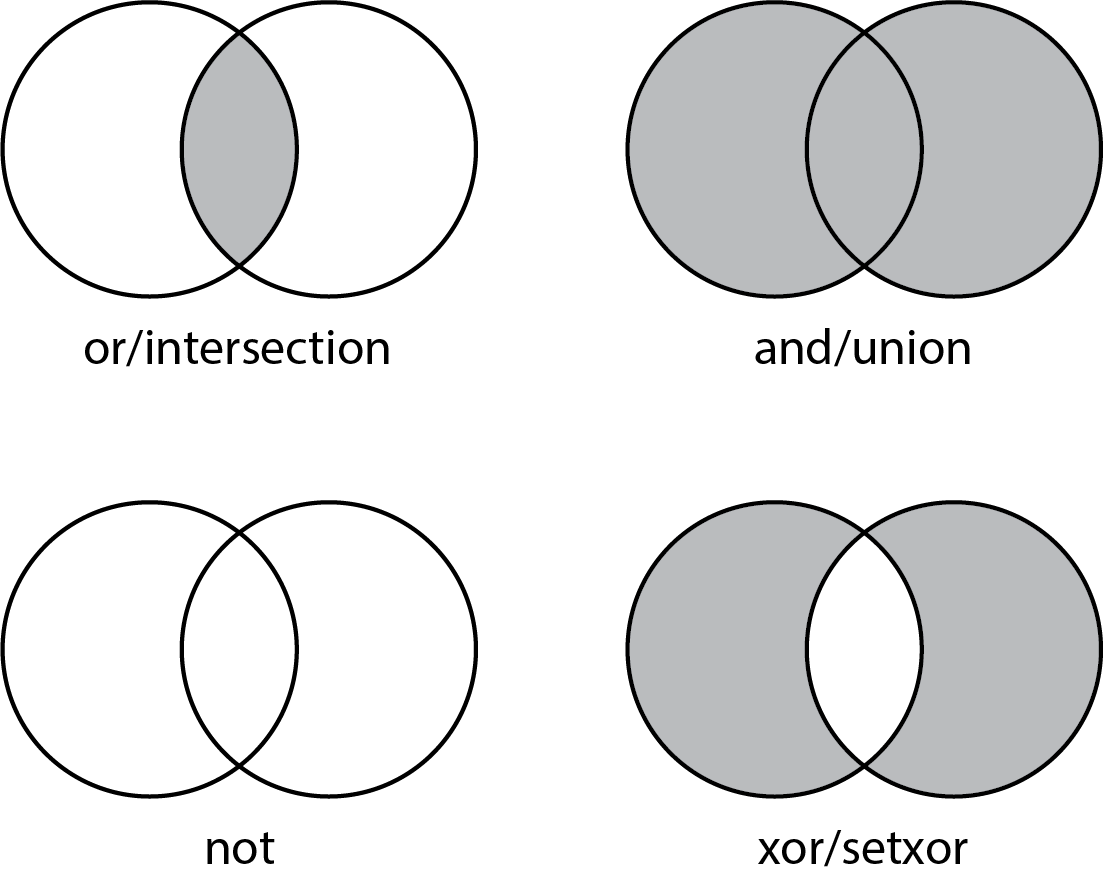

**Figure** *- Venn diagram shows the results of various set operations.  Each circle represents the set of data contained within a set with the overlapping region is common to both sets and the non-overlapping regions are unique to each set.  The grey region represents the result of a particular Boolean and/or set operator.*

Examples of specific operations on true/false values are shown below.

~[1 0]

ans = 1×2 logical array
   0   1



[1 1 0 0] & [1 0 1 0]

ans = 1×4 logical array
   1   0   0   0



[1 1 0 0] | [1 0 1 0]

ans = 1×4 logical array
   1   1   1   0



xor([1 1 0 0],[1 0 1 0])

ans = 1×4 logical array
   0   1   1   0


### 3.4 Set operations

There are a number of things you might want to do to a set or sets.  The set operations are summarized on the Venn diagrams above.  For instance, you might want to sort a set or find the unique values.

A = [3 7 4 4 1 3 5 8 5 9 0 0 3 4];

sort(A)

ans =      0     0     1     3     3     3     4     4     4     5     5     7     8     9



unique(A)

ans =      0     1     3     4     5     7     8     9


If you have two sets, you might want to find the intersection, union, or difference (setxor and setdiff).

B = [1 8 0 8 9 0 4 2 6 3 6 8];

C = intersect(A,B)

C =      0     1     3     4     8     9



C = setxor(A,B)

C =      2     5     6     7



C = union(A,B)

C =      0     1     2     3     4     5     6     7     8     9



C = setdiff(A,B)

C =      5     7


## 4. Basic Data Types

MATLAB has a limited number of basic data types: *double*, *char/string*, *logical* and *cell*.  Each have different properties that you will need to know.

### 4.1 Doubles

MATLAB has a basic numeric datatype called a *double*.  Unlike some languages that distinguish between integers and floating point numbers (those with a decimal), MATLAB does not automatically create variables other than *double*.  As a floating point number, a *double* precision number on a 64-bit machine is 8 bytes that ranges from 

% largest negative and positive numbers
-realmax,-realmax

ans = -1.7977e+308

ans = -1.7977e+308

% smallest (non-zero) negative and positive numbers
-realmin, realmin

ans = -2.2251e-308

ans = 2.2251e-308

Note the 'e+x' and 'e-x' indicates engineering notation for $\times 10^x$ and $\times 10^{-x}$.  If you try to set a number greater than one of these, you will get a number that is out of bounds

-2*realmax

ans = -Inf

2*realmax

ans = Inf

where *Inf* indicates infinite.  Another special type of double is NaN, which stands for 'not a number'.  You will obtain NaN's when the result of an operation is undefined, e.g.,

0/0

ans = NaN

You may also see NaN values in an array would be otherwise empty to serve as a placeholder.  Any operation that includes a NaN will result in a NaN so you may have to clean vectors of NaN's before performing functions.  You can get an index to all the values that have a NaN using isnan() and all the values that are not NaN using ~isnan(). 

### 4.2 Chars and Strings

The second common data type is a *char*, which includes a character.  You can group characters together to create a *char* array.  A *string* and a *char* are very similar except that a string can be thought of as the equivalent of a word or sentence.  Note single quotes encompassing characters creates a *char* whereas double quotes encompassing characters creates a string.

c = 'This is a char array'

c = 'This is a char array'

length(c)

ans = 20

s = "This is a string"

s = "This is a string"

length(s)

ans = 1

It is possible to convert a variable from from *char* to *string* using the string() function and possible to convert from *string* to *char* using the char() function.

string(c)

ans = "This is a char array"

char(s)

ans = 'This is a string'

Note the change in the number of quotes around the printed results.

It is also possible to convert from a *char* or *string* to a *double* using str2num().  The function works for both *char* and *string* arguments.

c = '20';
n = str2num(c)

n = 20

s = "40";
n = str2num(s)

n = 40

It is also possible to go in reverse, turning a number into a *char* array

n = 20;
c = num2str(n)

c = '20'

Most of the time we will use *char* and not *string* type variables so I will focus most of my discussion around the use of *char*.  The use of conditional tests may not work the way you want for *char*.  You can compare char arrays using strcmp() or strcmpi(), which tests if two *char* arrays are equivalent; case sensitive test for the former and case insensitive for the latter.  We will use these functions later to examine data classes.

c1 = 'value1';
c2 = 'VALUE1';
strcmp(c1,c2)

ans = logical
   0


strcmpi(c1,c2)

ans = logical
   1


You can change the case of characters using upper() and lower().  Note: I can include two single quotes without a character between to create an apostrophe in a char.

c = 'I''m NoT cRaZy'

c = 'I'm NoT cRaZy'

upper(c)

ans = 'I'M NOT CRAZY'

lower(c)

ans = 'i'm not crazy'

### 4.3 Logicals

A logical is a variable that contains *true* or *false* values in MATLAB.  Many of the particulars have already been covered in Section 2.3.  It is possible to create a logical variables by using logical().  Logical variables can also be created by assigning the results of conditional tests or as the result of some functions.

### 4.4 Cells

A *cell* is a variable type that is really more of a container than a type.  A *cell* allows one to hold any data type.  A cell isn't really useful on its own, but it can be very useful when used as an array because it can be used to store mixed types.

a = {10}

a = 1×1 cell array
    {[10]}


a = {'word'}

a = 1×1 cell array
    {'word'}


## 5. Working With Arrays

Many of the operations we will do require computing quantities at a number of positions, dealing with multiple data points, etc.  Hence, vectors and matrices are integral to the work we do.  MATLAB calls these arrays.  Arrays can be one-dimensional, row or column vectors, or N-multidimensional matrices, though you will rarely use more than two or three dimensions.

### 5.1 Creating Vectors

To create a vector you can enclose a series of numbers in square brackets

x = [1 2 3 4 5]

x =      1     2     3     4     5


You can also create a series using the colon (:) operator,

x = [1:5]

x =      1     2     3     4     5


It is possible to create a vector other than using the default step size of 1, by using three values separated by colons as *x = [start:step_size:end]*,

x = [2:2:10]

x =      2     4     6     8    10


The last way to create a vector is using the *linspace()* function, which will automatically determine the step size,

x = linspace(1,10,5)

x =     1.0000    3.2500    5.5000    7.7500   10.0000


Note that in each case, the default is a row vector.  It is possible to create a column vector either by using a semicolon (;) between the elements or by using the transpose operator, an apostrophe (').  You can guarantee a column vector using a (:)

x = [1;2;3;4;5]

x =      1
     2
     3
     4
     5


x = [1 2 3 4 5]

x =      1     2     3     4     5


x'

ans =      1
     2
     3
     4
     5


x(:)

ans =      1
     2
     3
     4
     5


We can do the same with char one-dimensional arrays,

x = 'abcde'

x = 'abcde'

x = x'

x = 5×1 char array
    'a'
    'b'
    'c'
    'd'
    'e'


x = ['a':'f']

x = 'abcdef'

s = ['a':2:'f']

s = 'ace'

### 5.2 Multidimensional Arrays and Matrices

Whereas a vector is 1xN (row vector) or Nx1 (column vector), an array has multiple dimensions and thus can be size MxN for a two-dimensional array or MxNxP for a three-dimensional array.  Below, I create a two-dimensional array of random numbers with 5 rows and 3 columns.

A = rand([5,3])

A =     0.8147    0.0975    0.1576
    0.9058    0.2785    0.9706
    0.1270    0.5469    0.9572
    0.9134    0.9575    0.4854
    0.6324    0.9649    0.8003


The nice thing about matrices and vectors in MATLAB is that performing math on them is quick and easy.  You can perform the operations the same way you would write a matrix equation on paper, following linear algebra rules.  For example, suppose I wanted to multiply the array above by a scalar value of 2.

2*A

ans =     1.6294    0.1951    0.3152
    1.8116    0.5570    1.9412
    0.2540    1.0938    1.9143
    1.8268    1.9150    0.9708
    1.2647    1.9298    1.6006


To multiply a matrix by a vector the inner dimensions must be the same, i.e., a matrix MxN can be right-multiplied by a column vector Nx1 or left-multiplied by a row vector 1xM in size.

x = [1:5]

x =      1     2     3     4     5


B = x*A

B =     9.8226   10.9497   10.9132


y = [1:3]'

y =      1
     2
     3


C = A*y

C =     1.4826
    4.3746
    4.0923
    4.2845
    4.9630


The inner dimensions of two matrices must also be equal in order to multiply

D = rand([2,5])

D =     0.1419    0.9157    0.9595    0.0357    0.9340
    0.4218    0.7922    0.6557    0.8491    0.6787


D*A

ans =     1.6901    1.7290    2.5944
    2.3492    2.0883    2.4184


E = rand([3,2])

E =     0.7577    0.6555
    0.7431    0.1712
    0.3922    0.7060


A*E

ans =     0.7517    0.6620
    1.2740    1.3267
    0.8781    0.8527
    1.5940    1.1053
    1.5101    1.1447


There are a few additional operations that may come in handy that are matrix operations.  These include:

### 5.3 Extracting elements

If you have created a variable, you can refer to all the elements stored within it by simply referring to its name.  But there are many instances in which you will only want one or a subset of elements.  Each element is referred to by an integer index value.  

x = rand([5 1])

x =     0.0318
    0.2769
    0.0462
    0.0971
    0.8235


% print the second element
x(2)

ans = 0.2769

For multidimensional arrays, there is an index for each dimension (subindices) or you can use a single index value that refers to the individual element position, which is counted by row and then by columns.

y = magic(5)

y =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9



% extract the 9th element
y(9)

ans = 12


% extract the value in the 4th row and 2nd column
y(4,2)

ans = 12

You can convert the major index to the subindices by ind2sub() and the opposite by sub2ind()

[i,j] = ind2sub([5 5],9)

i = 4

j = 2


k = sub2ind([5 5],i,j)

k = 9

You can extract multiple elements from a matrix by providing an array of multiple indices.

y([4 3],[2 1])

ans =     12    10
     6     4


You can also extract single columns or single rows using a ':' to indicate all elements along a specific dimension.

% a single row
y(3,:)

ans =      4     6    13    20    22


% a single column
y(:,4)

ans =      8
    14
    20
    21
     2


## 6. Advanced Data Types

### 6.1 Structures

When we pass variables to and from functions it can be very annoying to list every one, especially if it needs to be done several times.  It can also be helpful to group variables together that relate in some way.  For example, imagine you create a 3D model.  You might have a vector for locations in x, y, and z.  You might have grids of properties that relate to the field you are modeling as well as the field itself.  Rather than have an independent variable for each one, we can stick them all into a container called a structure.  A structure allows us to give each one a name (field).  Each field can be different lengths or a different type.  When we pass the contents of a structure to a function, we need only reference its name than pass each of the individual components.

You can address each field of a structure using a dot reference of the form *struct_name.field_name*.

core.company = 'Rad Minerals'

core = struct with fields:
    company: 'Rad Minerals'


core.location = [-34.22, 102.78];
core.sample_depths = [99.1; 105.4; 106.3; 115.3];
core.analyte = {'K','U','Th'};
core.analyte_method = {'x-ray spectroscopy'};
core.concentrations = [0.9234 0.9797 0.4087;
    0.4302 0.4389 0.5949;
    0.1848 0.1111 0.2622;
    0.9049 0.2581 0.6028];

core

core = struct with fields:
           company: 'Rad Minerals'
          location: [-34.2200 102.7800]
     sample_depths: [4×1 double]
           analyte: {'K'  'U'  'Th'}
    analyte_method: {'x-ray spectroscopy'}
    concentrations: [4×3 double]


Note that some of the values are hidden from view when you print out the record to keep the output relatively small.  But the data are there and can be viewed by typing *struct_name.field_name*.

core.concentrations

ans =     0.9234    0.9797    0.4087
    0.4302    0.4389    0.5949
    0.1848    0.1111    0.2622
    0.9049    0.2581    0.6028


It is possible to create an array of structure types if needed.  This is one way a database can be constructed.

### 6.2 Tables

Tables are a relatively recent addition to MATLAB, added to version 2013b and have fast become my favorite datatype for dealing with data.  A lot of data we use are tabulated; for example, an Excel spreadsheet with each row a sample and each column an id, analyte or metadatum.  We can exploit this tendency by having a set of functions written specifically to handle data in a tabular form.  A  table allows us easily reference analytes while also making it easy to pass entire tables to custom functions for processing without the need for multiple variables.  A table in many ways is like a structure, except every field must be the same length.  Any empty positions are replaced by an empty char for char fields and NaNs for numeric fields.  Tables can easily be read in from an Excel spreadsheet (*.xls, *.xlsx) or a comma delimited text file (*.csv) using *readtable(filename)*.

If your Excel table is transposed, meaning each column is a sample and each row is a field, then you will need to do a little more work to get your data into the appropriate table format.

You can other options as necessary if you have header lines that you do not wish to read, there are multiple worksheets and you want one other than the first worksheet.  Basically, there is some flexibility.

You can write a table back to a file just as easily with *writetable(filename)*.

Let's look at some basic things we can do with a table.  Besides reading a table, we can create one from existing variable:

LastName = {'Sanchez';'Johnson';'Li';'Diaz';'Brown'};
Age = [38;43;38;50;59];
Smoker = logical([1;0;1;0;1]);
Height = [71;69;64;67;64];
Weight = [176;163;131;133;119];
BloodPressure = [124 93; 109 77; 125 83; 117 75; 122 80];

T = table(LastName,Age,Smoker,Height,Weight,BloodPressure)

T = 5×6 table
     LastName      Age    Smoker    Height    Weight    BloodPressure
    ___________    ___    ______    ______    ______    _____________

    {'Sanchez'}    38     true        71       176       124     93  
    {'Johnson'}    43     false       69       163       109     77  
    {'Li'     }    38     true        64       131       125     83  
    {'Diaz'   }    50     false       67       133       117     75  
    {'Brown'  }    59     true        64       119       122     80  


Now that we have a table T, lets play with it.  We can produce a summary statistics for each column.

summary(T)


Variables:

    LastName: 5×1 cell array of character vectors

    Age: 5×1 double

        Values:

            Min        38  
            Median     43  
            Max        59  

    Smoker: 5×1 logical

        Values:

            True        3    
            False       2    

    Height: 5×1 double

        Values:

            Min          64   
            Median       67   
            Max          71   

    Weight: 5×1 double

        Values:

            Min         119   
            Median      133   
            Max         176   

    BloodPressure: 5×2 double

        Values:
                      BloodPressure_1    BloodPressure_2
                      _______________    _______________

            Min             109                75       
            Median          122                80       
            Max             125                93       



We can extract individual variables for processing in several ways.

Suppose we wanted the age, height, and weight of the individuals.  You could refer to them by the column numbers as you would a matrix,

T{:,[2,4,5]}

ans =     38    71   176
    43    69   163
    38    64   131
    50    67   133
    59    64   119


Or you could to them by name, which is incredibly useful when tables have lots of columns.

T.Age

ans =     38
    43
    38
    50
    59


T{:,{'Age','Height','Weight'}}

ans =     38    71   176
    43    69   163
    38    64   131
    50    67   133
    59    64   119


Note the use of {} creates an array from the table.  If you wanted to return a new table with just those three columns, use () instead of {}

T(:,{'Age','Height','Weight'})

ans = 5×3 table
    Age    Height    Weight
    ___    ______    ______

    38       71       176  
    43       69       163  
    38       64       131  
    50       67       133  
    59       64       119  


Tables can be incredibly useful because the can be very quick to filter and organize data.  Suppose you wanted to divide the smokers and non-smokers for analysis, you can use logical relations to separate the data.

ind = T.Smoker == 1;
S = T(ind,:)

S = 3×6 table
     LastName      Age    Smoker    Height    Weight    BloodPressure
    ___________    ___    ______    ______    ______    _____________

    {'Sanchez'}    38     true        71       176       124     93  
    {'Li'     }    38     true        64       131       125     83  
    {'Brown'  }    59     true        64       119       122     80  


NS = T(~ind,:)

NS = 2×6 table
     LastName      Age    Smoker    Height    Weight    BloodPressure
    ___________    ___    ______    ______    ______    _____________

    {'Johnson'}    43     false       69       163       109     77  
    {'Diaz'   }    50     false       67       133       117     75  


Something else you might want to do to a table is sort it.  For example, suppose you wanted to sort the table based on the last name,

sortrows(T,'LastName')

ans = 5×6 table
     LastName      Age    Smoker    Height    Weight    BloodPressure
    ___________    ___    ______    ______    ______    _____________

    {'Brown'  }    59     true        64       119       122     80  
    {'Diaz'   }    50     false       67       133       117     75  
    {'Johnson'}    43     false       69       163       109     77  
    {'Li'     }    38     true        64       131       125     83  
    {'Sanchez'}    38     true        71       176       124     93  


Sorting will work on char/string or numeric fields, but not cell or structures.  You can sort arrays using the sortrows() command and vectors using the *sort()* function.

## 7. Programs, Scripts and Functions

A program self-contained computer code that one can execute and often interact with.  Nowadays, programs are often referred to as apps (short for applications).  Programs are often compiled and therefore the code cannot be changed by the user.  A script is simply a sequence of computer code but are not programs in the formal sense.  A script is generally written or can be modified by the user.  A function is generally a short(ish) section of code that performs one or more basic operations that can be utilized by a script multiple times if necessary.  A function is written to reduce the length of programs/scripts and improves their readability.  A function may be part of a single program/script, or it may be used in multiple scripts.

MATLAB is a program and allows one to write applications (including ones with graphical user interfaces) with in it, but most of the time, you will write scripts and occasionally functions.

### 7.1 Functions

The first line of a function starts with a declaration which includes 4 parts: 1. the keyword *function*; 2. the output variables; 3. the function name; and 4. the input variables.  The input and output variables are also called arguments.  A function ends with the keyword *return*.  Actually, *return* is not strictly necessary in MATLAB unless the function is ended as part of a conditional test.  However, I consider it good practice to use a *return* statement as the last line of a function only to make the end of a function explicit.

When calling a function, the keyword is excluded.  The input and output variable names from the calling source do not have to be the same as the names within the function declaration.  It is only the position of the variables that matter.

Variables have a property that is called scope, which means where it is valid.  Variables within a function are limited in scope to the function itself.  Aside from global variables, whose use is generally discouraged unless absolutely required, the only way to send information to a function is through the input variables.  Likewise the only way to pass information to the workspace, script or original function that called the current function is through output variables.  The memory stored during the operation of a function is cleared when the function ends.

Variables stored in the scope outside a function will not affect the values of a variable with the same name within a function.

Functions can also have scope.  They have a *.m extension in MATLAB.  Multiple functions can be placed within a single file.  The first function listed in the file can be called externally.  All other functions can only be called from the first function within the file.  You might want to have functions within functions for readability, or if you would otherwise write the same/similar blocks of code multiple times.  Why not just create a new file so the internal function could be used elsewhere?  Probably because you don't see the need for using it as part of other functions or applications.  For example, some plotting functions I make will only be internal to a function because they set a number of properties of the plot specific to the current problem.

Help for a function is created automatically by the first continuous block of comments in a *.m file.

### 7.2 Scripts

A script is also stored in a *.m file.  A script is really just a stored sequence of code that is saved to whenever required.  The scope of variables within a script includes the workspace.  This behavior is different from a function, which cannot access the workspace variables directly.  Why write scripts and not functions?  Perhaps because you wish to process a dataset, storing the result to the workspace where you extract portions of the data to produce a variety of plots.  Because you may not have settled on the final form of the figures, you may experiment with options on the command line.  Doing so will prevent the need for having to re-run the script/function from the beginning every time you change or add a line of code.

MATLAB has another type of script which they call live scripts (*.mlx files) that are a way to blend writing with code used to create the figures in a document.  If the user has the data files used to create a live script, they can edit the code and alter the figures.  This tutorial is written in a live script.  Within live scripts, the code can be separated into sections using a section break.  When you change the code, the entire document can be run, or a single section of code can be run by typing the key combination Ctrl+Enter (on Windows) or ⌘+Return.

## 8. Reading and Writing Data Files

We will be working with data, which means that we will need to load the data into MATLAB.  While you can copy and paste it into MATLAB, that would be silly.  There are several in-built commands that can be used to load data, but they work for specific formats.  You can write a custom program to read just about any format data that data are stored in, but it can be a pain and should only be reserved for cases where you will need to read many similar files or you will do it frequently.  If you are only dealing with a couple of files, it may be easier and/or faster to reformat the data into one of the standard forms.  Fortunately most data we use are in tabular form, for many of these cases you will want to use the *readtable()* function for xlsx and csv tables that have headers.  An alternative function for reading tabular data is the *load()* function.  It will return the data in the form of a numeric array.

Load is also used to read MATLAB native formats.

To write data, use the *save()* command.  You can save all the variables in MATLAB's native format for loading at some time later by simply typing,

This is one of the faster formats for MATLAB to load so if you don't need to us the output somewhere else it is a useful format.  You can also save selected variables using this command,

Note that the variable names are provided as strings.  You can also save a variable in a csv format that you can read into Excel or Notepad or some other text processor.  You will need to add '-ascii' to the end save arguments so MATLAB knows to store the data in a text format.

If you are using tables, you can write a table with the *writetable()* function.

To read and write more complicated or binary file formats you can use *fopen(), fread(), fgetl(), fwrite(), fprintf()*, etc.  These functions are based on the C programming language.  Since these are significantly more advanced commands I won't cover them here, but it is useful to know that they exist if you need them in the future.  

## 9. Plotting Data

Much of the utility of a programming language like MATLAB is its ability to simply plot data with minimal effort.  There are an incredibly large number of types of plots that you can produce.  You also have a LOT of flexibility to alter and improve the plots you make and you can make publication quality figures with relatively minimal effort.  I'll cover several basic plotting commands here that you are most likely to use, including annotations.

It is also possible to develop your own custom plotting functions.  You'll see a few examples in the course that I've developed for my own use (e.g., ternary diagrams and radar plots).

### 9.1 Plotting points and lines

The plot function you are most likely to use is called *plot()*.  It is used to plot cartesian (x,y) data.  Plot is fairly versatile.  It allows you to produce points and lines with various colors and styles.  By default plot() will produce a line.

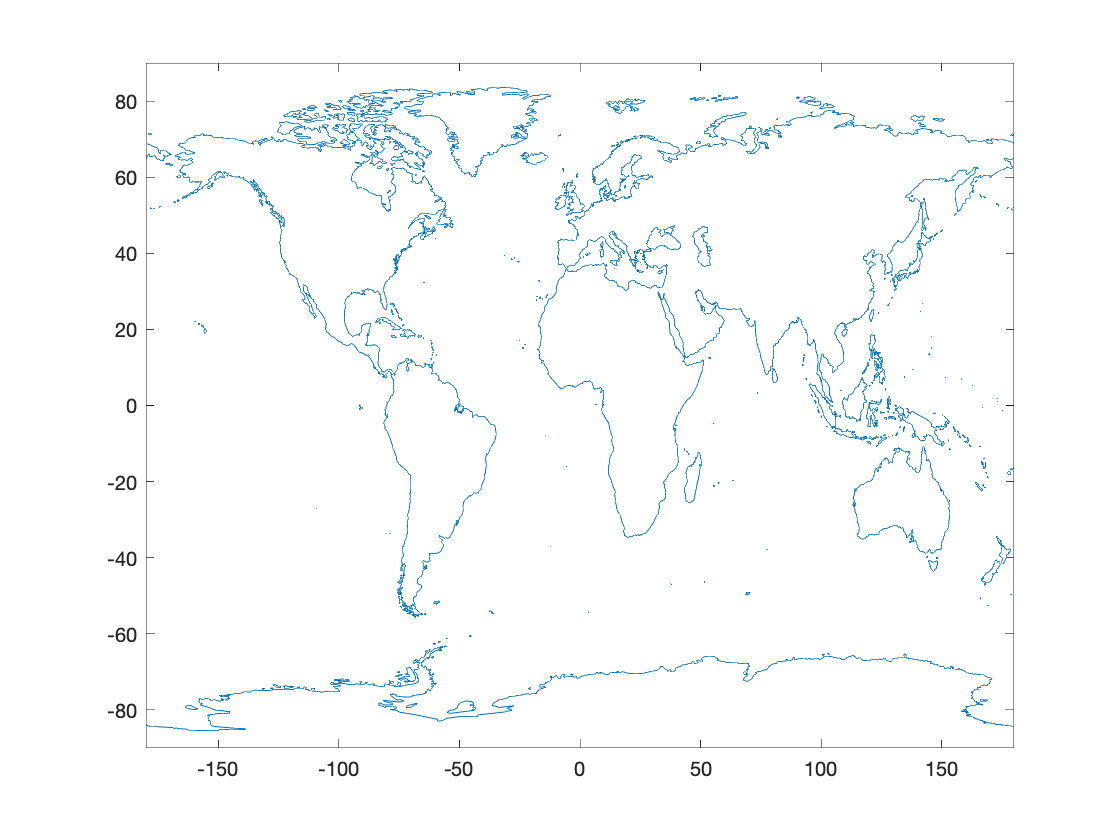

% coast.mat includes a global coastline stored in (clon,clat)
load('coast.mat');

% start a new figure with the figure command
figure;
% default plot produces a line
plot(clon,clat);
axis([-180 180 -90 90])

You can change the style and color of the default lines using a style string, which can include a color, symbol and/or line style.  The options for plot are shown in the table below, which can also be found in 'help plot'.

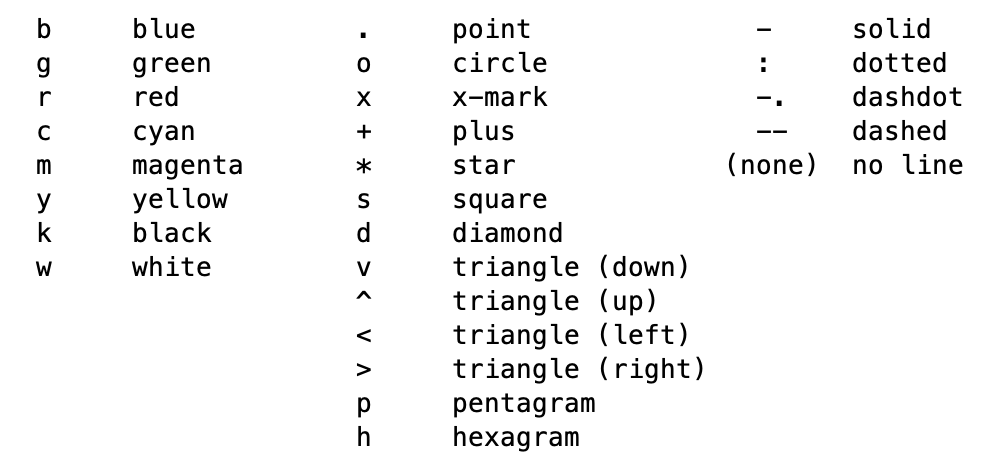

For example, a plot of volcanic hotspot localities is created using red triangles at the current hotspot positions.

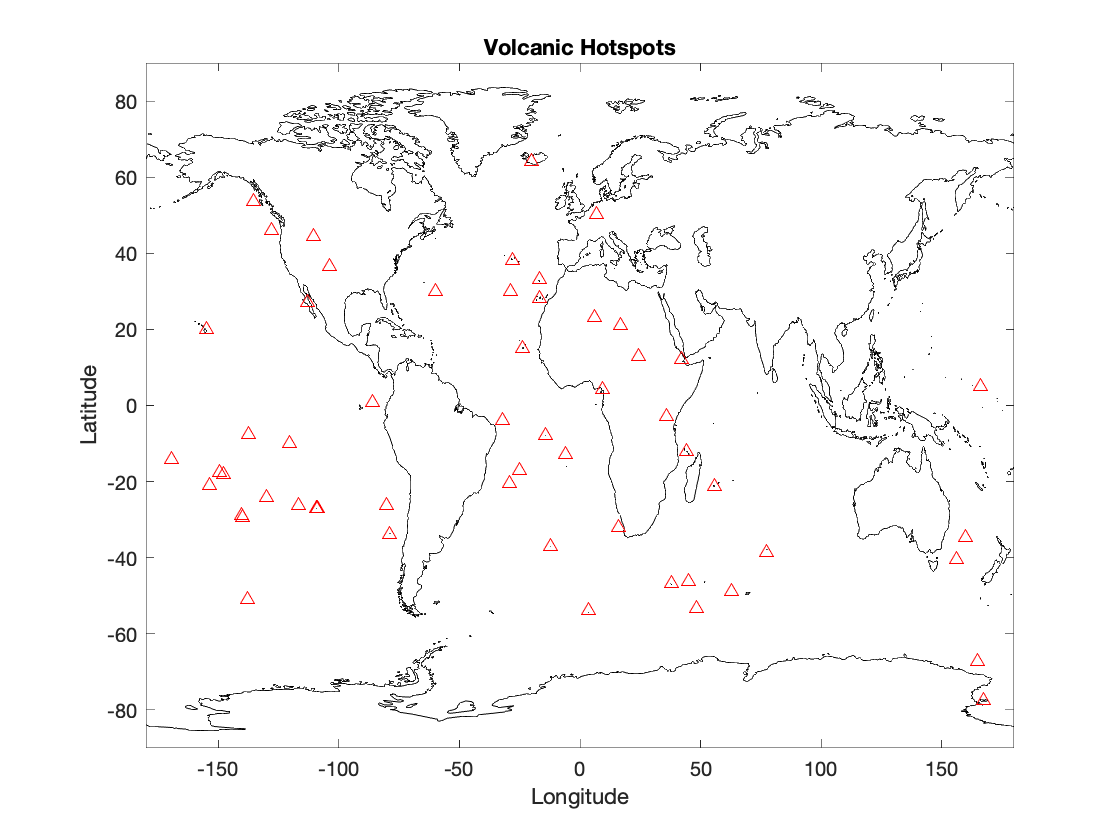

hotspots = readtable('hotspots.csv');
% a plot of hotspots
figure;
plot(clon,clat,'k-');
axis([-180 180 -90 90])
hold on;
plot(hotspots.longitude,hotspots.latitude,'r^');
xlabel('Longitude');
ylabel('Latitude');
title('Volcanic Hotspots');

There are a number of annotations that can be added to plots, including

A scatter plot is not much different from a plot function using symbols, except that it allows you to color and change the size of symbols using a set of values.

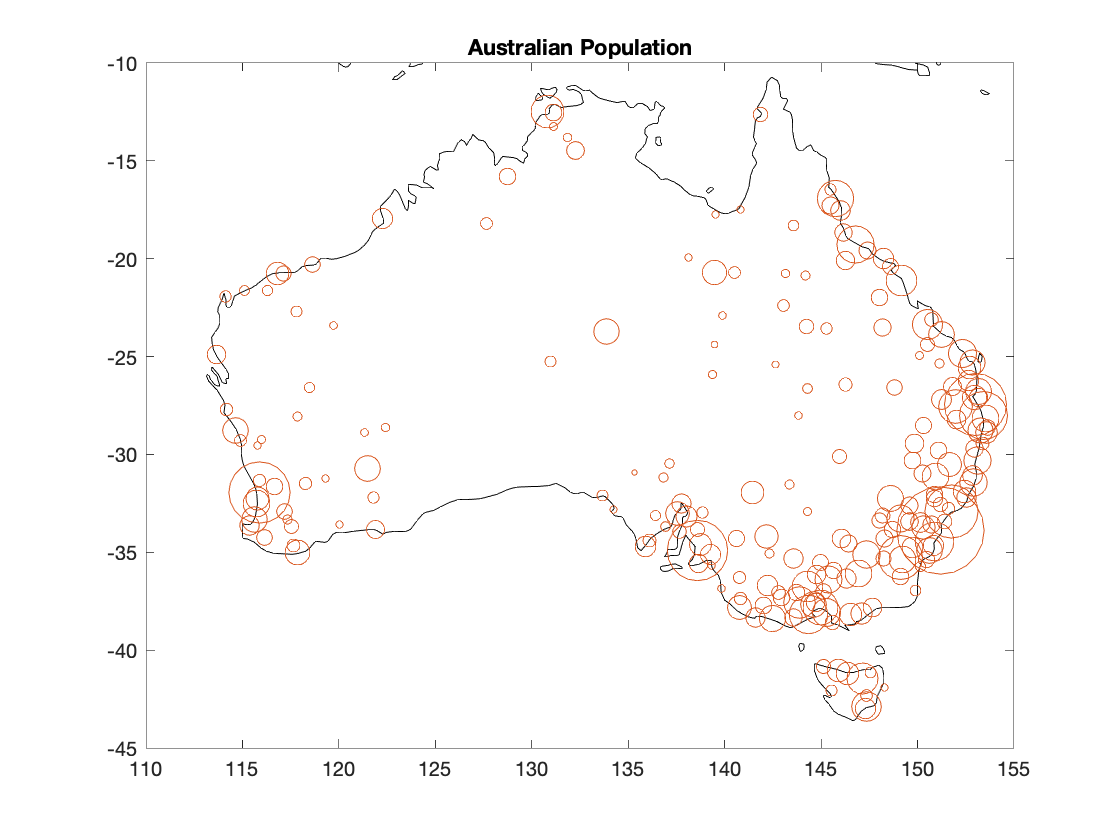

% I'll start by plotting a coastline
figure;
plot(clon,clat, 'k-');
% hold on prevents the figure from being overwritten when I add the scatter plot
hold on;  

% read a database of australian cities
aus_cities = readtable('aus_cities.xlsx');

% plot the city locations with the size determined by the population of the
% metro area
% note that sometimes scaling the bubbles right can be a bit of a pain,
% which is why in this case I take the square root of the population to
% produce a both reasonably sized and range of bubbles.
scatter(aus_cities.longitude, aus_cities.latitude, sqrt(aus_cities.population_municipal));
title('Australian Population');
xlim([110 155])
ylim([-45 -10])

### 9.2 Histograms, bars and pies

A histogram is a bar plot, where values are grouped into bins and displayed on the vertical axis with the height of bars indicating the counts, probability, or probability density.  Histogram can also be used to produce cumulative distributions (we'll look at these further in the course).

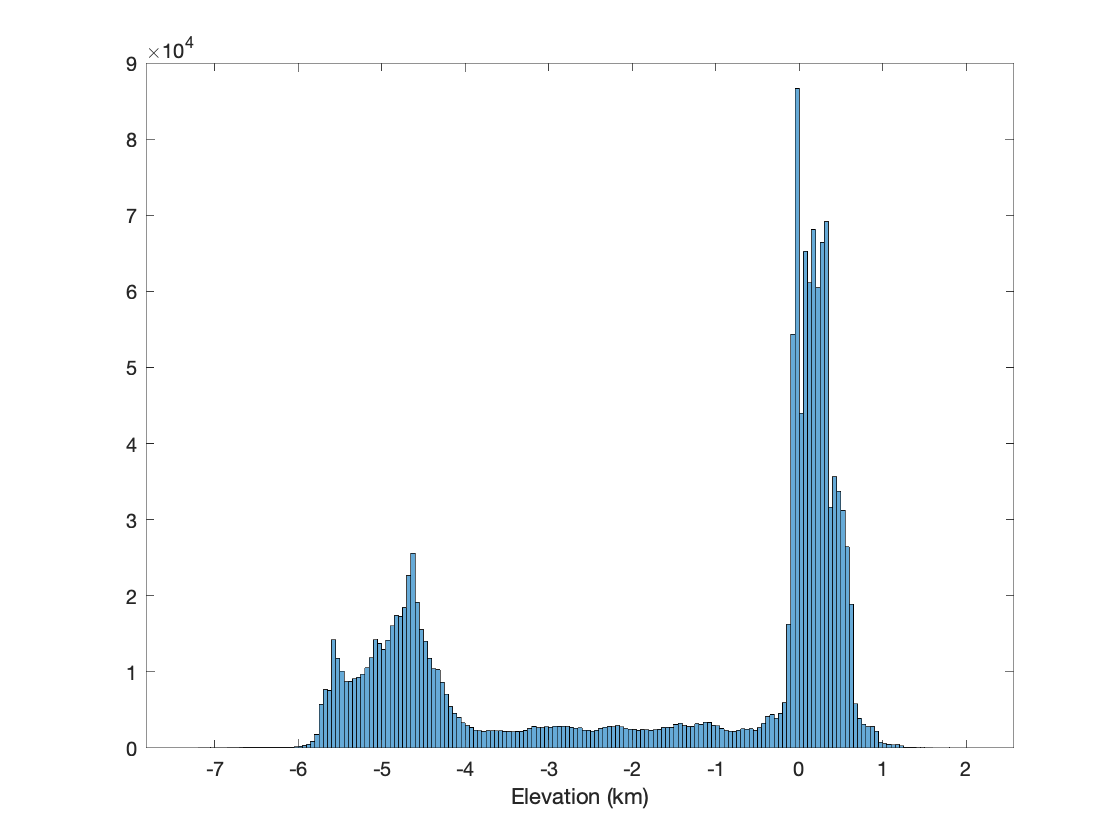

load('aus_elev.mat');
elev = elev; % convert from m to km

figure;
histogram(elev);
xlabel('Elevation (km)');

A pie chart is sort of like bar plot when all the bars represent parts of a whole.  In a pie chart the size of the pie slice represents the fraction of the total given by a category.

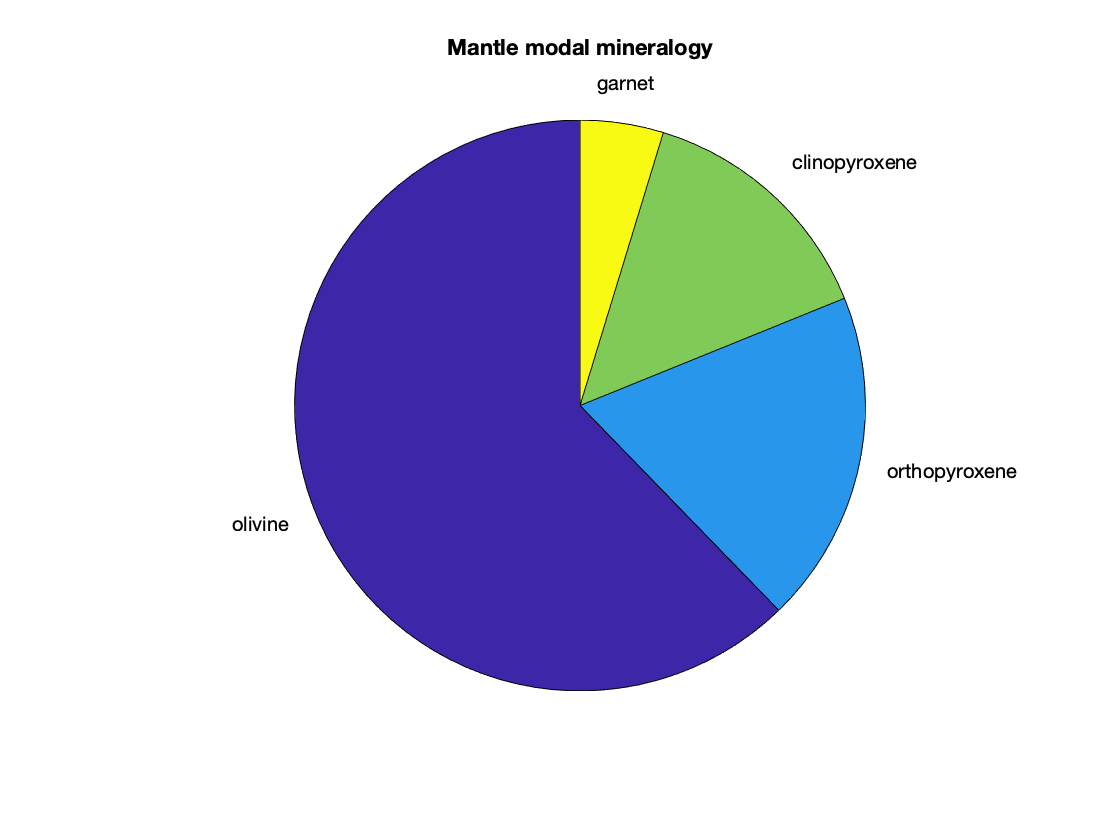

figure;
pie([66 20 15 5],{'olivine','orthopyroxene','clinopyroxene','garnet'});
title('Mantle modal mineralogy');

### 9.3 Gridded data plots

There are quite a few 2D/3D plot types that that can be used to plot a matrix of values.  I have made a number of these below to show you some of the differences between them.

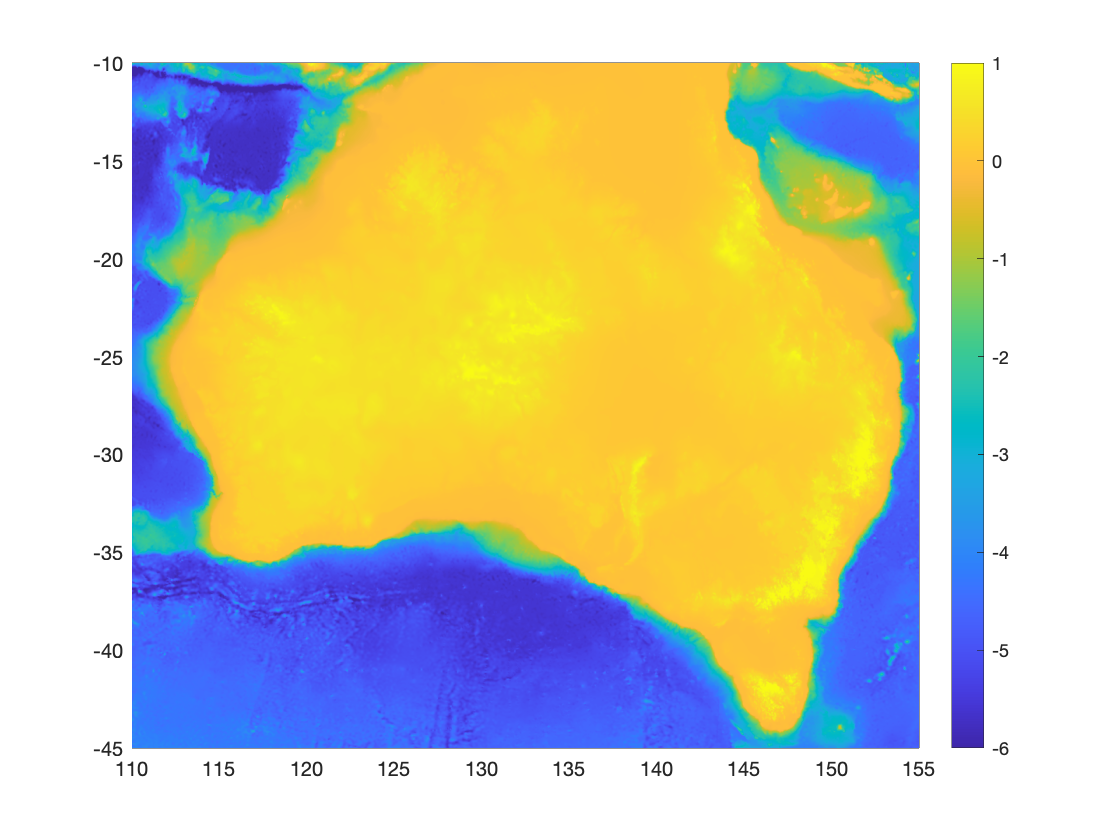

figure;
pcolor(elon,elat,elev);
shading flat;
colorbar;
caxis([-6 1]);

A surface plot is very similar to a pcolor plot except you can include a second matrix as the color information for the plot.  In the plot below, I have added sediment thickness as the color to be displayed over topography.  I have also added lighting which creates the appearance of topography.  By default surface is 2D, but you can make it 3D by using the command view(3).

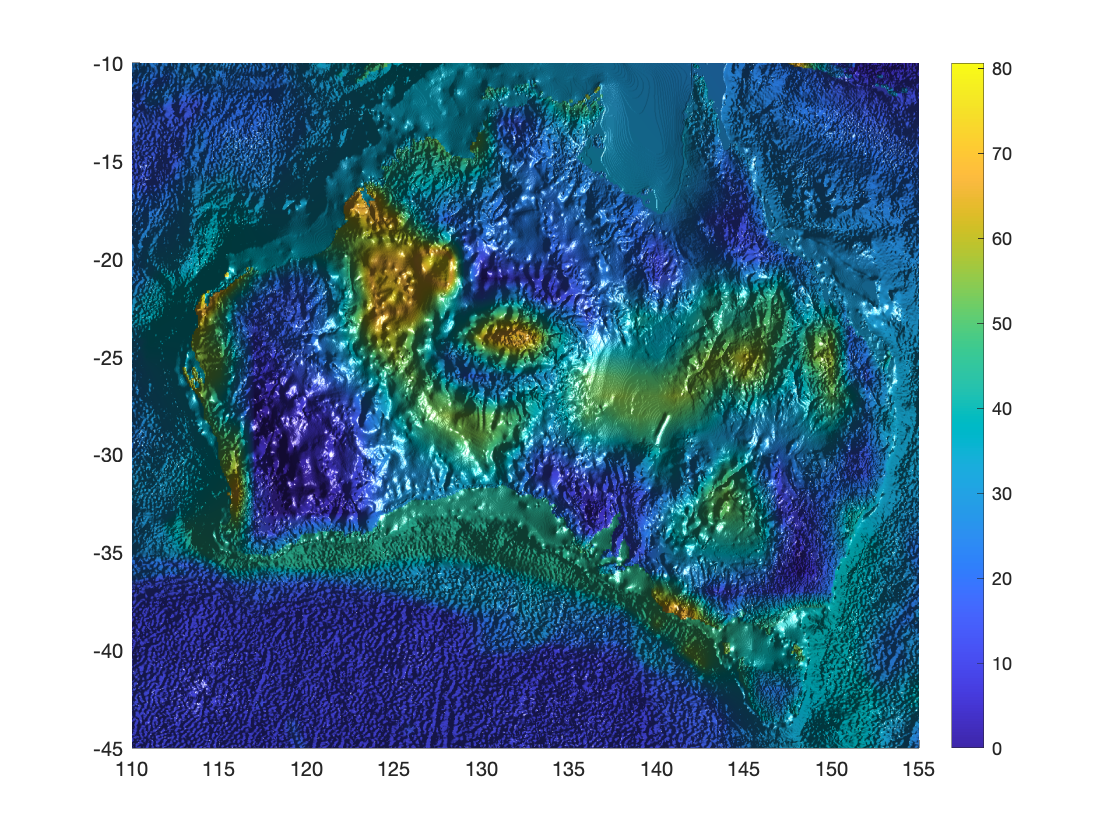

figure;
surface(elon,elat,elev,sqrt(sed));
shading flat;
colorbar;
%view(3)
lightangle(gca,70,30)

Mesh creates a wire frame that can be colored and shaded.  With the number of points in this topography dataset the gaps disappear.

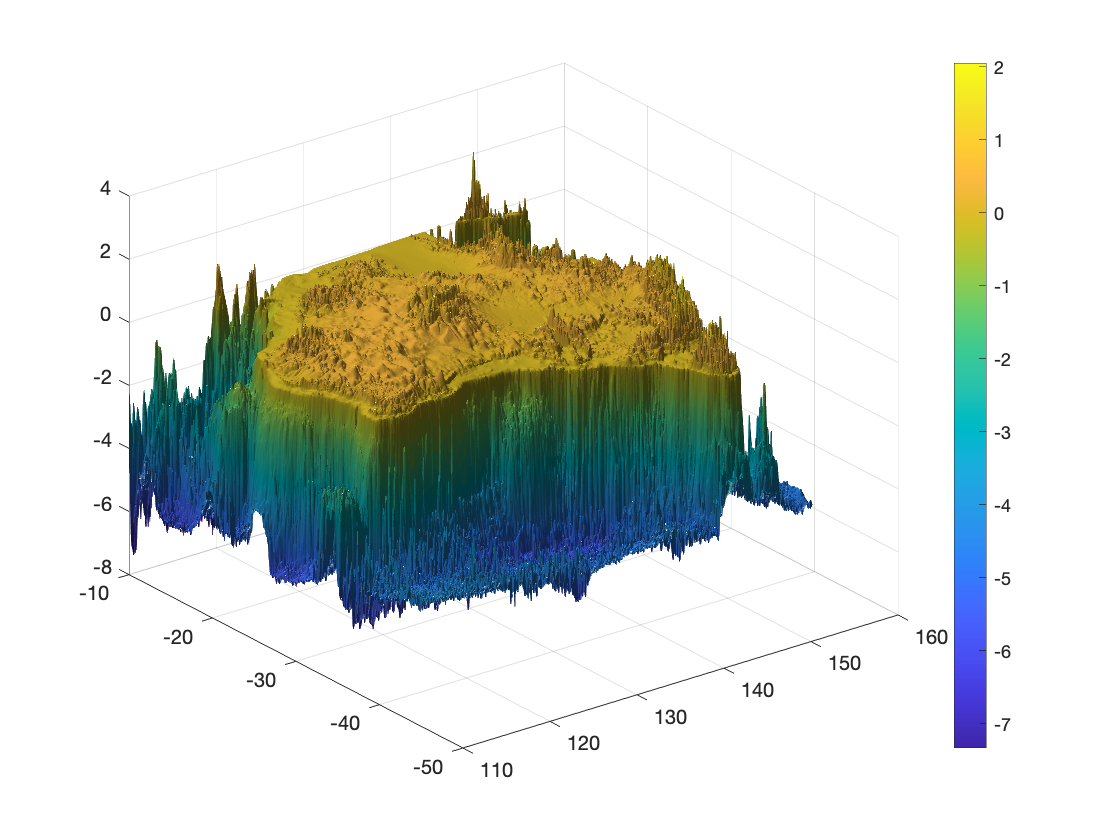

figure;
mesh(elon,elat,elev);
colorbar;
lightangle(gca,70,-60)

A contour plot only requires three arguments just the plots above, but I have added a fourth that includes a vector of contour levels.

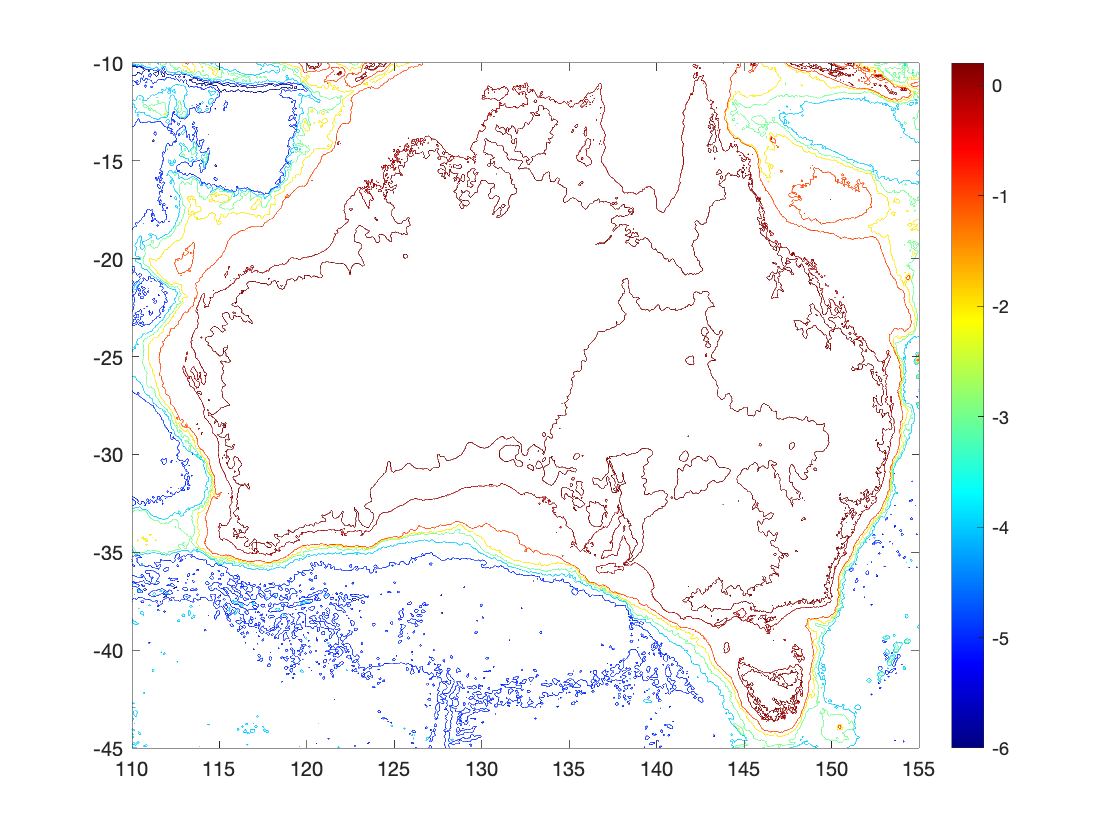

figure;
contour(elon,elat,elev,[-6:0 0.2:1]);
colormap jet
colorbar;

Imagesc can be much faster to plot than some of the other methods because it treats the background image like a tiff or jpg.  By default, the origin of an image is in the upper left corner (*axis ij*).  To plot with the origin in the lower left corner you will need to add the line *axis xy*.

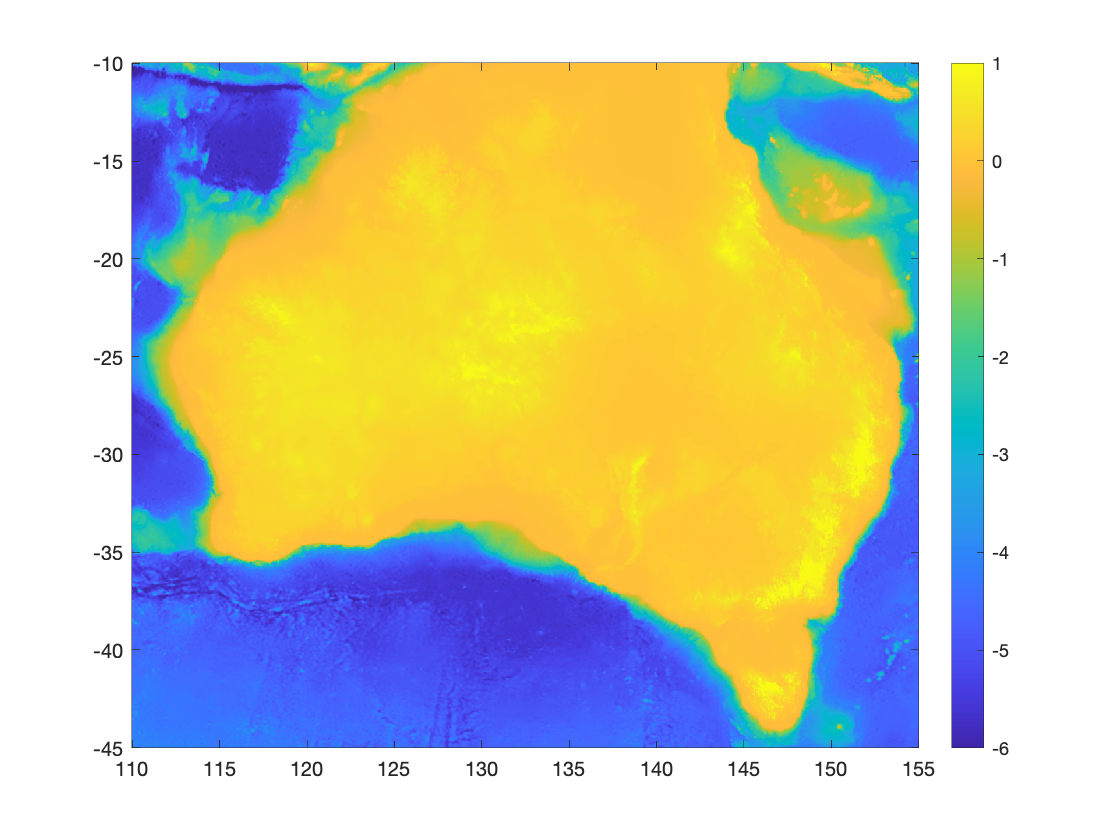

figure;
imagesc(elon,elat,elev);
colorbar;
caxis([-6 1]);
axis xy;

Quiver can be used to plot directional information.  The plot below is the topographic gradient for a small section of the maps above.  By giving quiver a return value of h, we have access to graphics handles, which are discussed more below.

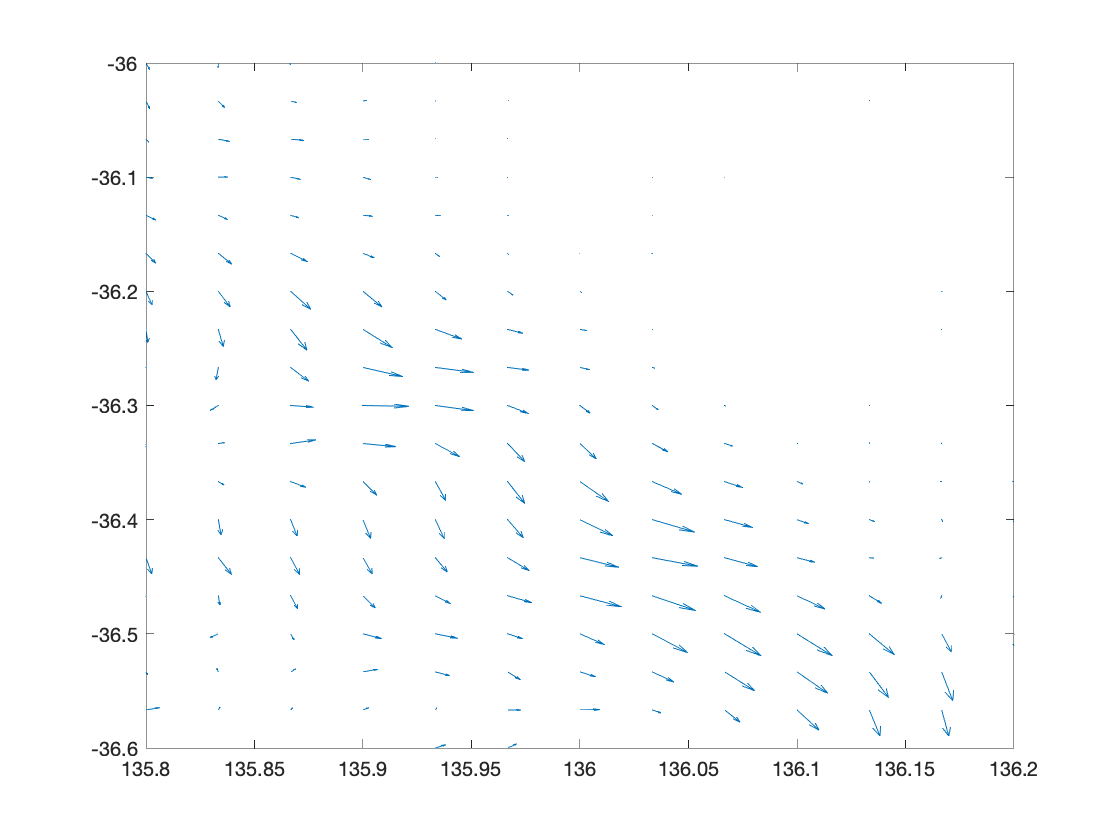

[dex,dey] = gradient(elev);
[X,Y] = meshgrid(elon,elat);

figure;
h = quiver(X,Y,dex,dey);
axis ([135.8 136.2 -36.6 -36]);

### 9.4 Mapping

MATLAB has a mapping toolbox that allows you to make geographic plots.  I won't really go into this because it is a little more specialized and we won't really be using it, but it is good to know that it exists.  Help map will give you a list of plotting functions and other geographic functions.  One thing that I've found useful lately is the use of shapefiles within MATLAB, specifically shapefile polygons that I can then use to filter and analyze data.

### 9.5 Graphics handles

Graphics handles make plots very customizable with relatively little effort, giving you control over nearly every aspect of a plot.  Most plot types will return a graphics handle, which is a MATLAB graphics object (kinda like a structure) that contains the editable properties of a plot and their present values.  There are a few special handles for a plot that are created when you call any plot command including **gcf** (handle to currently selected figure), **gca** (handle to currently selected axes), and **gco** (handle to currently selected graphics object).  Below are some graphics handles.  You can change most of the values as if you were assigning a new value to the structure field.

gcf

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 166
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


gca

ans =   Axes with properties:

             XLim: [135.8000 136.2000]
             YLim: [-36.6000 -36]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


h

h =   Quiver with properties:

        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [1051×1351 double]
        YData: [1051×1351 double]
        ZData: []
        UData: [1051×1351 double]
        VData: [1051×1351 double]
        WData: []

  Show all properties


## 10. Basic Code

### 10.1 If Statements

An *if* statement allows you to set up lines of code that are only executed if a specified condition is met.

### 10.2 Switches

A *switch* is very similar to an *if* statement except that the test value is predetermined.  This can make the code more efficient to run (faster).  In today's world, there is little benefit in terms of execution speed, but it can at times make code a little easier to read.

### 10.3. Try/Catch

Any errors resulting from a *try* block will be caught and a different set of code run.  Typically when an error is thrown, the program/script will stop functioning.  Catching an error allows the code to continue running without stopping when an error is thrown.  This behavior can be advantageous when you are trying to open a file and the program cannot find it, or when the error may not be crucial to the overall functioning of the code.

### 10.4 For Loops

A for loop allows you to repeat a section of code a specified number of times.

The above example will produce a loop that steps from the start_value to the end_value with a step size of one.  To specify a step size that is not one, start_value:step_size:end_value.  Loop variables in MALAB do not need to be integers, but if you use them as index values into variables they will need to be positive integers.  You can create loops where the loop where the index decreases, but an additional step size will need to be specified.

### 10.5 While Loops

A while loop allows you to repeat a section of code an unspecified number of times subject to a conditional being met

### 10.6 Break and Continue

There are two additional keywords that are useful when using loops.  The first is break which allows you end a for loop before all the iterations are complete.  It can also be used to end a while loop.

Continue is used to skip code in a for or while loop.

## Exercises

Create a new MATLAB live script so that you can type your responses and keep a record of your work.  We will go over the answers in the first day of the course.

- Open MATLAB and create a row vector with 10 values and a step size of 4.  Save it into a variable.

- Convert the row vector to a column vector and save it into a new variable.

- Create a vector with 100 rows using the randn() function.  Type *help randn* to see how to use it.

- Create a histogram from the random vector you just produced.

- Use *readtable()* to load arc_hp.csv.

- Using the arc data, make a *scatter()* plot of elevation versus Moho depth.

- Make a new plot using the same data but add errorbars to the plot using the function *errorbar()*.  Type *help errorbar* to see how to use it.

- Filter the arc data to create a new table from only the continental samples.  Note you will need to use *strcmp()*.  Use *help strcmp* to find out how to use it.

- Determine which arcs are below sea level by filtering the data.